# Sampling and Sunspots

## ***Section 1: Sampling***

## Part A

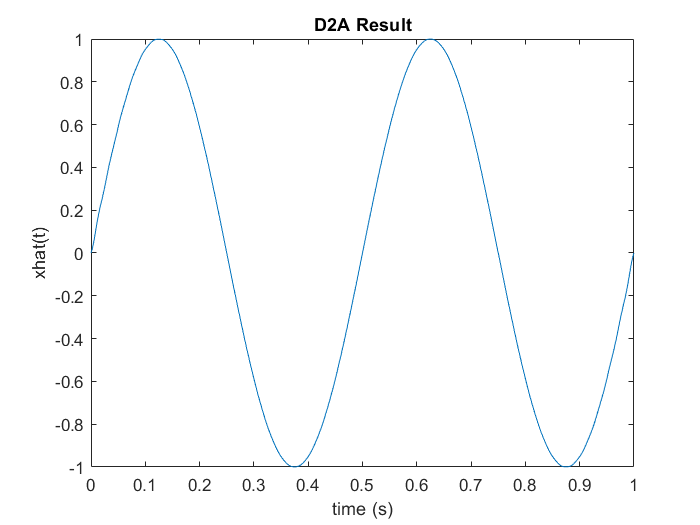

N = 100;
n = 0:N;
T = 1/100;
f = 2;

x = sin(2*pi*f*n*T);

[xhat,t] = PROJECT1(x,N,T);

plot(t,xhat)
xlabel('time (s)')
ylabel('xhat(t)')
title('D2A Result')

## Part B

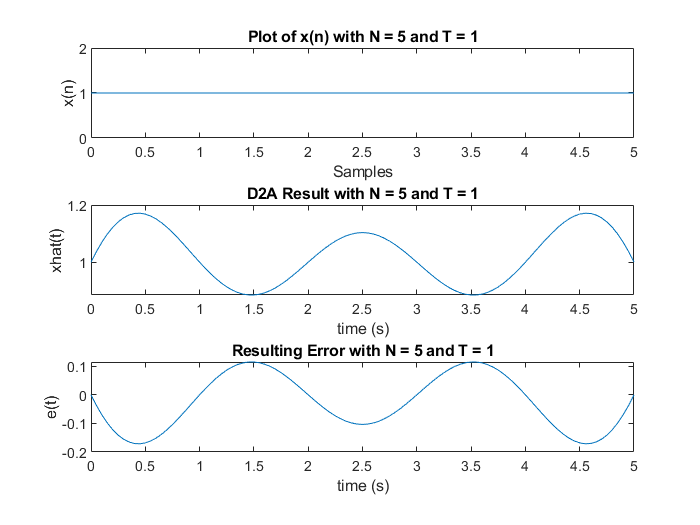

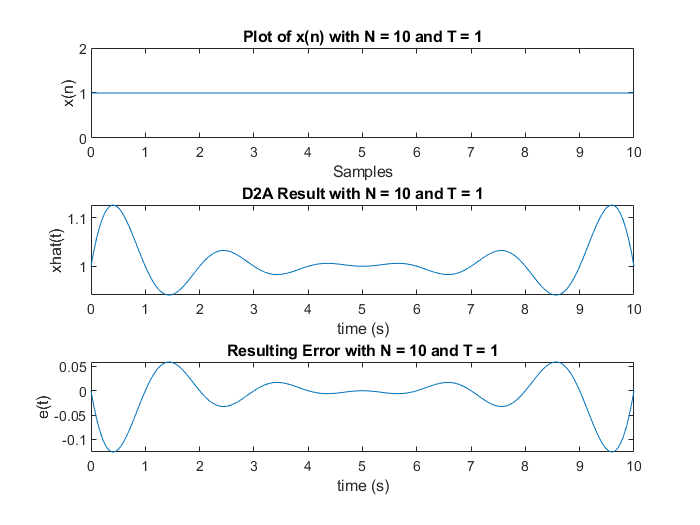

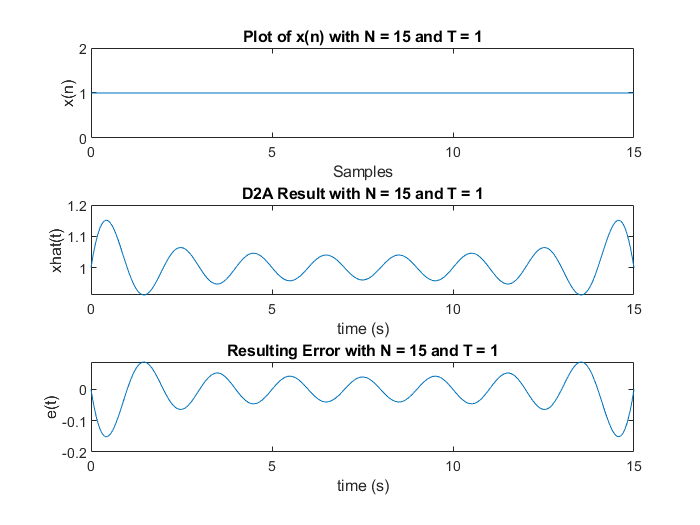

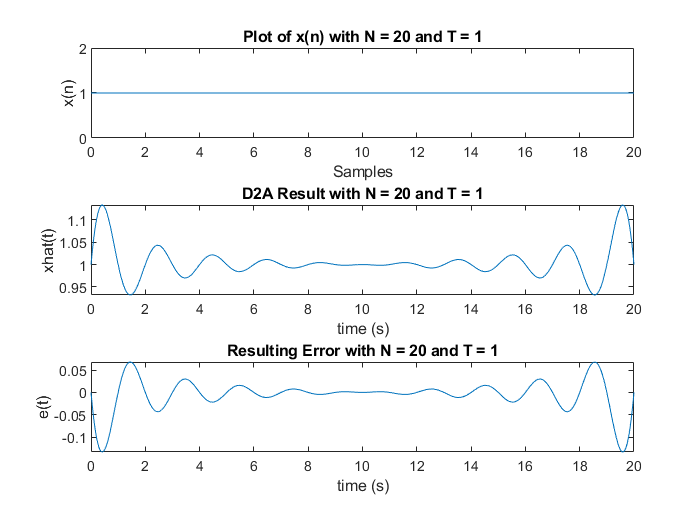

T = 1;
for N = 5:5:20
    x = ones(1,N+1);
    [xhat,t] = PROJECT1(x,N,T);
    xa = ones(1,length(t));
    e = xa - xhat;
    figure
    subplot(3,1,1);
    plot(0:length(x)-1,x)
    xlabel('Samples')
    ylabel('x(n)')
    title(sprintf('Plot of x(n) with N = %d and T = 1',N))
    
    subplot(3,1,2);
    plot(t,xhat)
    xlabel('time (s)')
    ylabel('xhat(t)')
    title(sprintf('D2A Result with N = %d and T = 1',N))
    
    subplot(3,1,3);
    plot(t,e)
    xlabel('time (s)')
    ylabel('e(t)')
    title(sprintf('Resulting Error with N = %d and T = 1',N))
end

## Part C

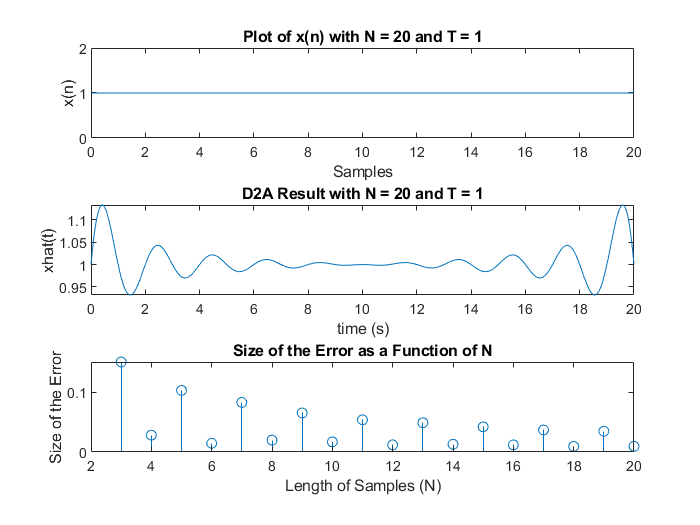

T = 1;
e_max = zeros(1,18);
for N = 3:20
    x = ones(1,N+1);
    [xhat,t] = PROJECT1(x,N,T);
    xa = ones(1,length(t));
    e = xa - xhat;
    e_max(N-2) = max(abs(e(round(1/3*length(xa)):round(2/3*length(xa)))));
end
stem(3:length(e_max)+2,e_max)
xlabel('Length of Samples (N)');
ylabel('Size of the Error');
title('Size of the Error as a Function of N');

## Part D

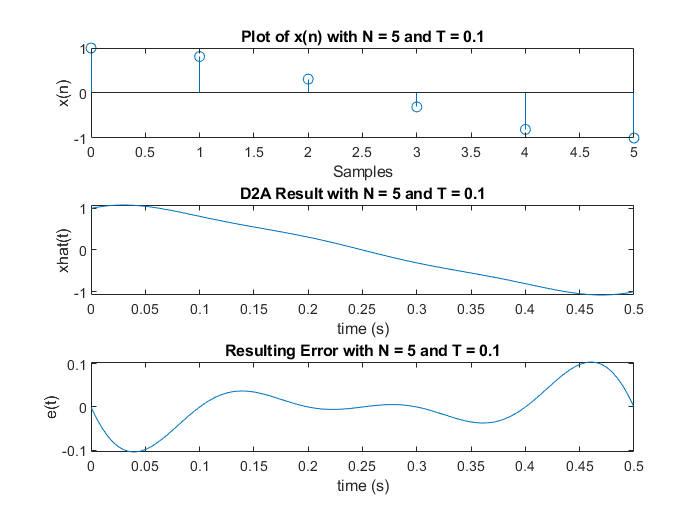

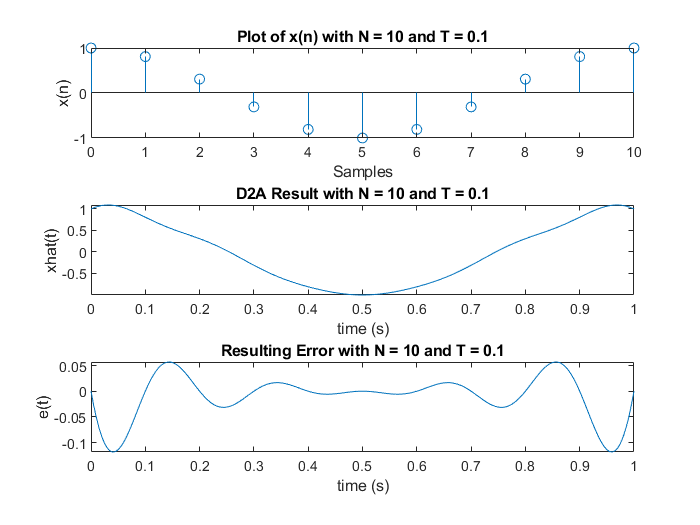

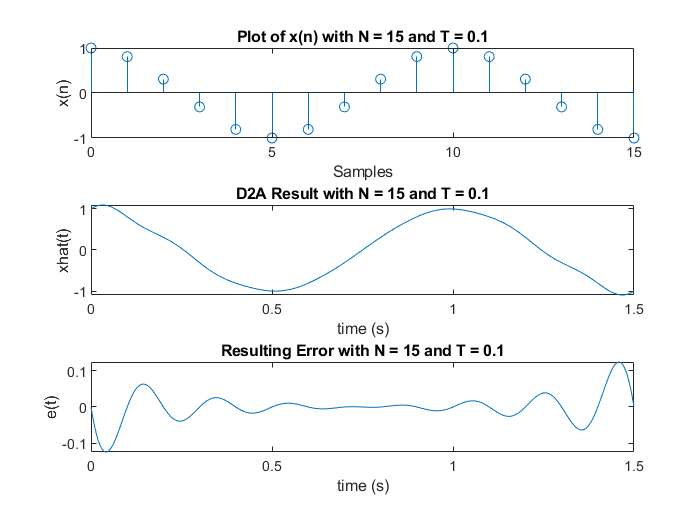

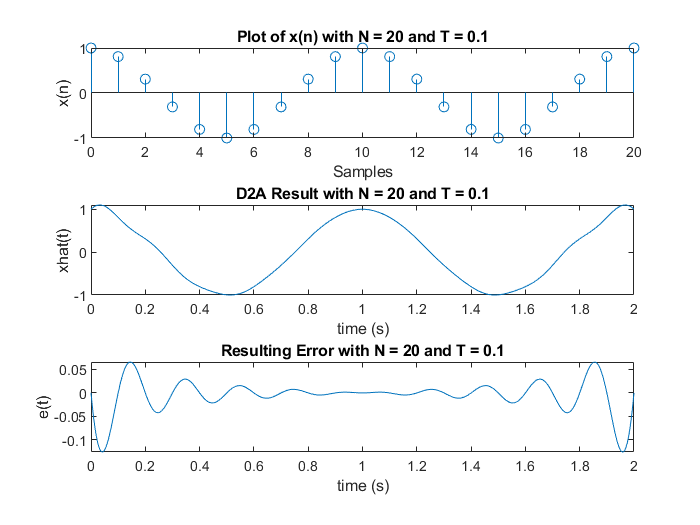

for N = 5:5:20
    F = 1;
    T = 0.1;
    n = 0:N;
    Theta = 0;
    x = cos(2*pi*F*T*n + Theta);
    [xhat,t] = PROJECT1(x,N,T);
    xa = cos(2*pi*F*t + Theta);
    
    e = xa - xhat;
    figure
    subplot(3,1,1)
    stem(0:length(x)-1,x)
    xlabel('Samples')
    ylabel('x(n)')
    title(sprintf('Plot of x(n) with N = %d and T = 0.1',N))
    
    subplot(3,1,2)
    plot(t,xhat)
    xlabel('time (s)')
    ylabel('xhat(t)')
    title(sprintf('D2A Result with N = %d and T = 0.1',N))
    
    subplot(3,1,3)
    plot(t,e)
    xlabel('time (s)')
    ylabel('e(t)')
    title(sprintf('Resulting Error with N = %d and T = 0.1',N))
end

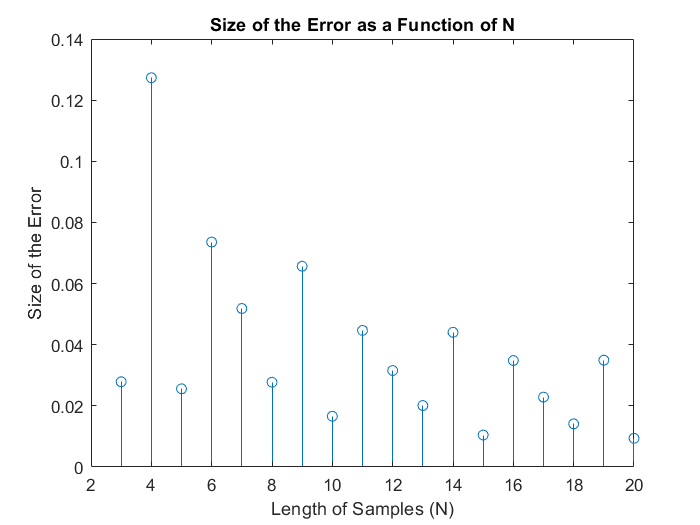

e_max = zeros(1,18);
for N = 3:20
    n = 0:N;
    x = cos(2*pi*F*T*n + Theta);
    [xhat,t] = PROJECT1(x,N,T);
    xa = cos(2*pi*F*t + Theta);
    e = xa - xhat;
    e_max(N-2) = max(abs(e(round(1/3*length(xa)):round(2/3*length(xa)))));
end
figure
stem(3:length(e_max)+2,e_max)
xlabel('Length of Samples (N)');
ylabel('Size of the Error');
title('Size of the Error as a Function of N');

## Part E

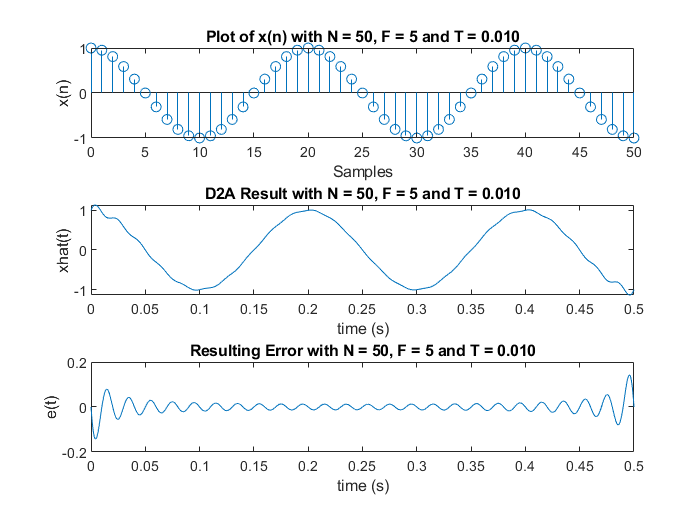

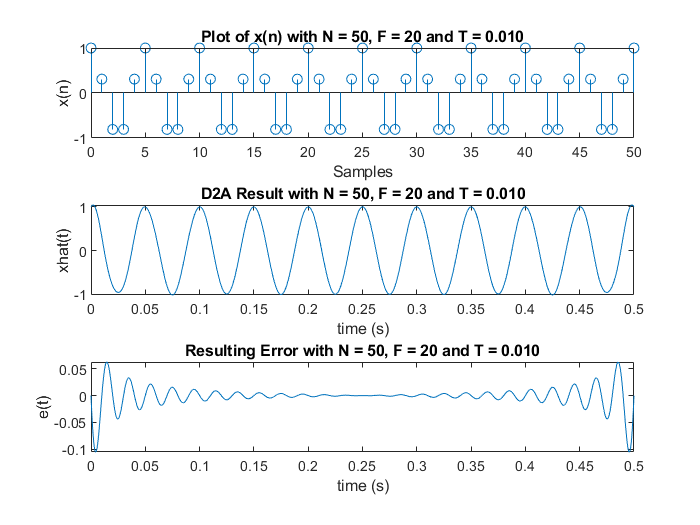

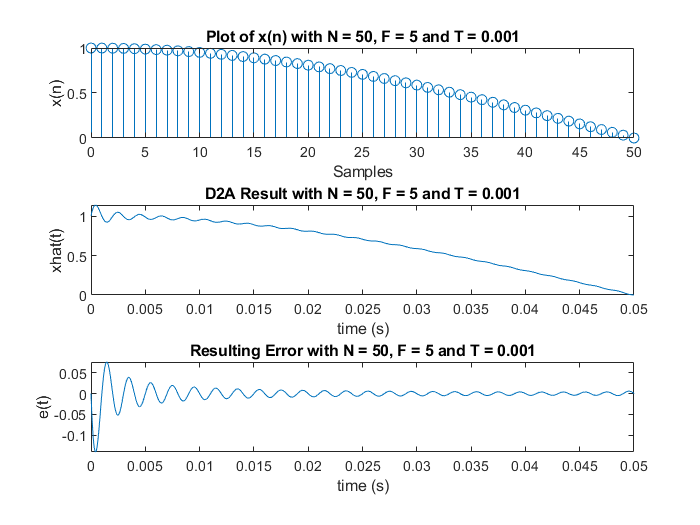

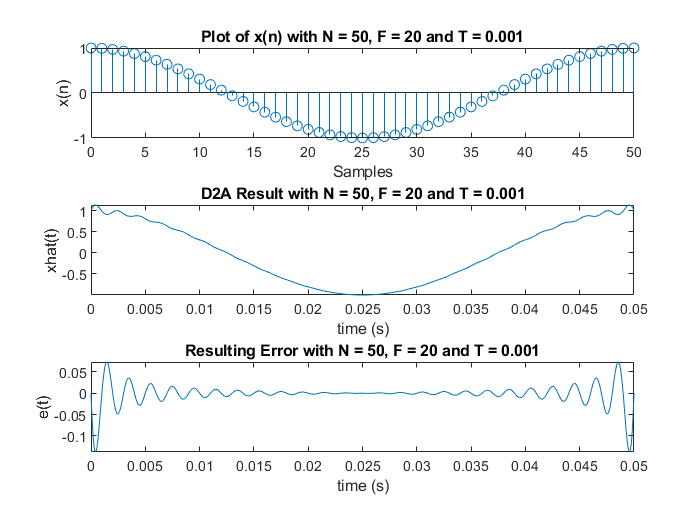

for T = [0.01 0.001]
    for F = [5 20]
        N = 50;
        n = 0:50;
        Theta = 0;
        x = cos(2*pi*F*T*n + Theta);
        [xhat,t] = PROJECT1(x,N,T);
        xa = cos(2*pi*F*t + Theta);
        
        e = xa - xhat;
        figure
        subplot(3,1,1)
        stem(0:length(x)-1,x)
        xlabel('Samples')
        ylabel('x(n)')
        title(sprintf('Plot of x(n) with N = %d, F = %d and T = %1.3f',N,F,T))
        
        subplot(3,1,2)
        plot(t,xhat)
        xlabel('time (s)')
        ylabel('xhat(t)')
        title(sprintf('D2A Result with N = %d, F = %d and T = %1.3f',N,F,T))
        
        subplot(3,1,3)
        plot(t,e)
        xlabel('time (s)')
        ylabel('e(t)')
        title(sprintf('Resulting Error with N = %d, F = %d and T = %1.3f',N,F,T))
    end
end

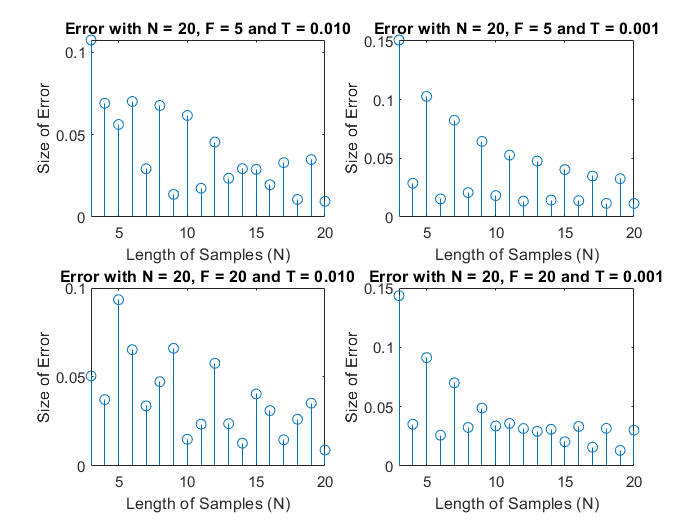

T1 = [0.01 0.001]; F1 = [5 20]; e_max = zeros(1,18); figure
for ii = 1:2
    for jj = 1:2
        for N = 3:20
            n = 0:N;
            T = T1(ii);
            F = F1(jj);
            x = cos(2*pi*F*T*n + Theta);
            [xhat,t] = PROJECT1(x,N,T);
            xa = cos(2*pi*F*t + Theta);
            e = xa - xhat;
            e_max(N-2) = max(abs(e(round(1/3*length(xa)):round(2/3*length(xa)))));
        end
        subplot(2,2,ii+2*(jj-1))
        stem(3:length(e_max)+2,e_max)
        xlim([3,20])
        xlabel('Length of Samples (N)');
        ylabel('Size of Error');
        title(sprintf('Error with N = %d, F = %d and T = %1.3f',N,F,T))
    end
end

## Part F

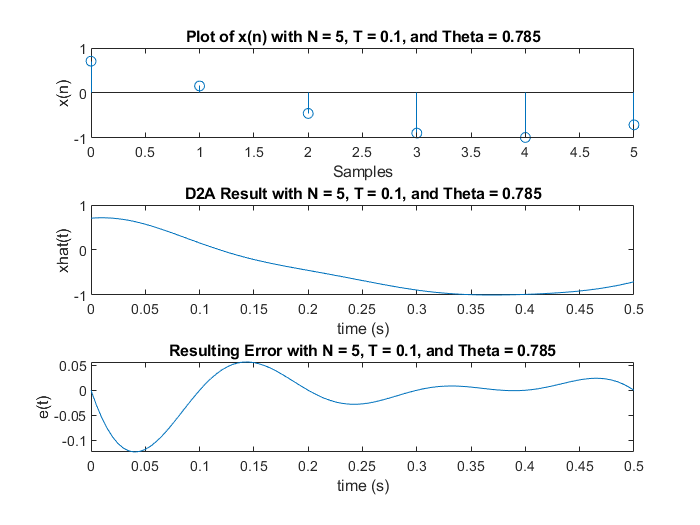

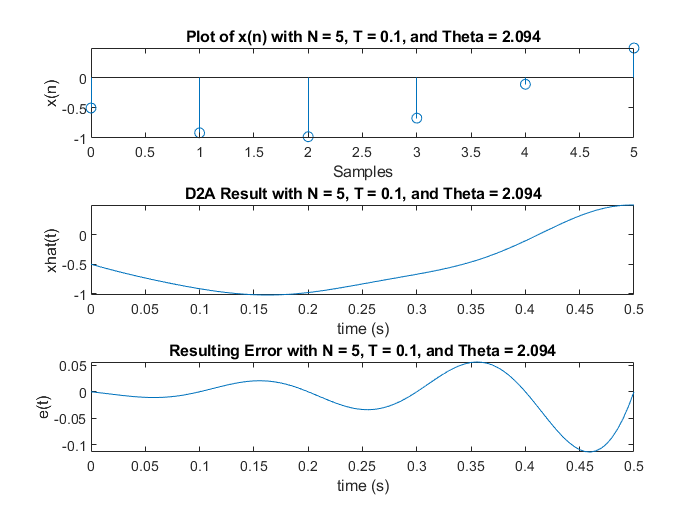

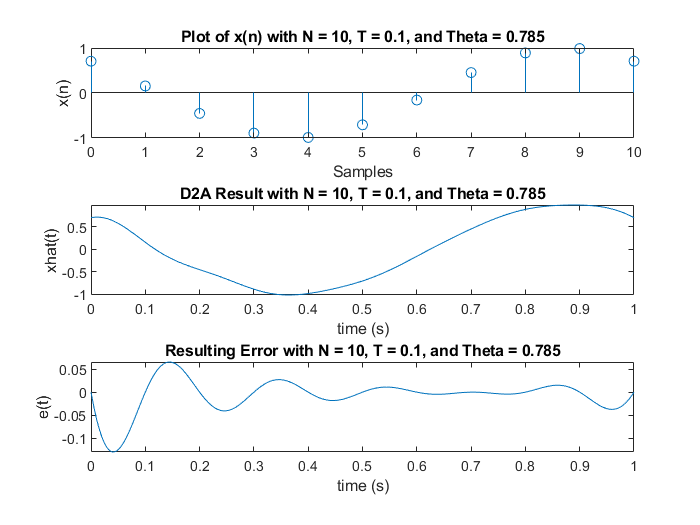

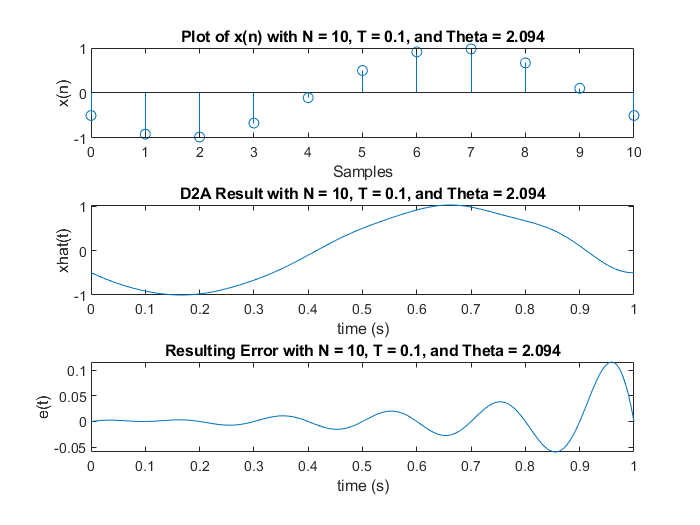

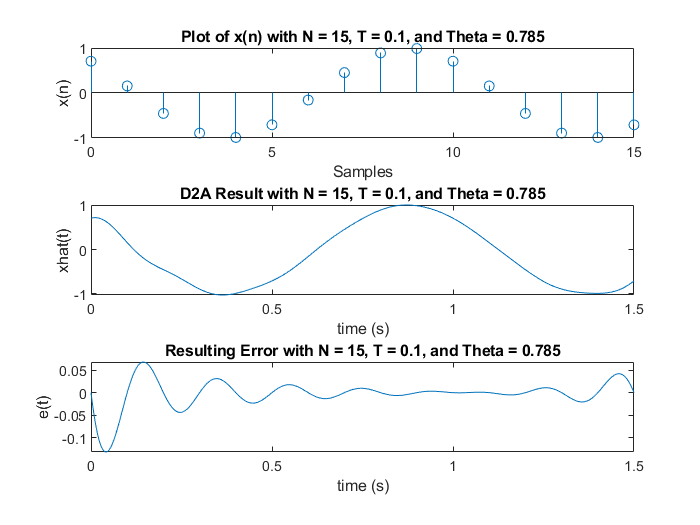

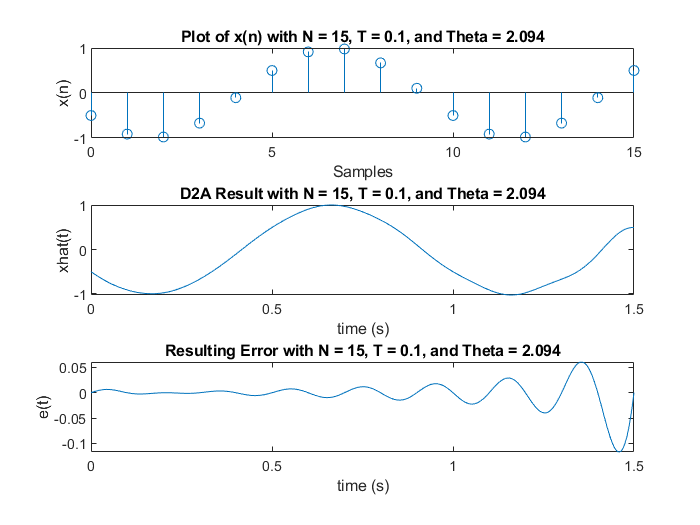

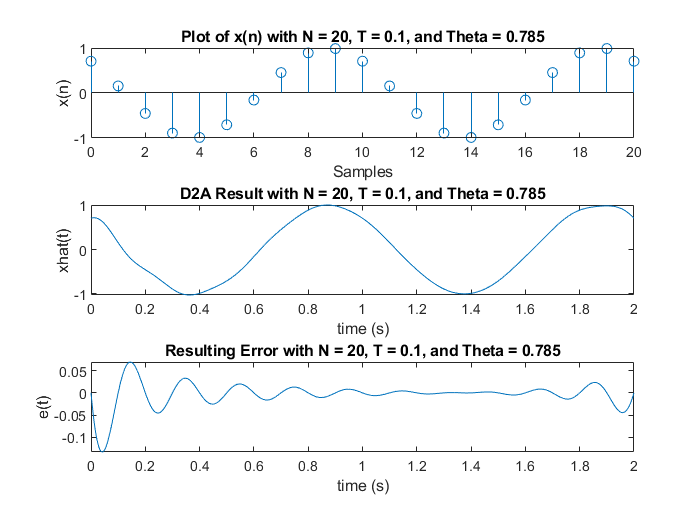

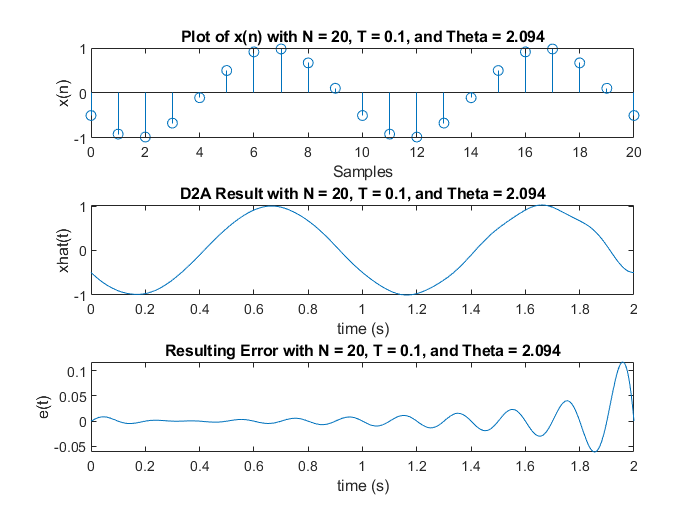

for N = 5:5:20
    for Theta = [pi/4 2*pi/3]
        F = 1;
        T = 0.1;
        n = 0:N;
        x = cos(2*pi*F*T*n + Theta);
        [xhat,t] = PROJECT1(x,N,T);
        xa = cos(2*pi*F*t + Theta);
        
        e = xa - xhat;
        figure
        subplot(3,1,1)
        stem(0:length(x)-1,x)
        xlabel('Samples')
        ylabel('x(n)')
        title(sprintf('Plot of x(n) with N = %d, T = 0.1, and Theta = %1.3f',N,Theta))
        
        subplot(3,1,2)
        plot(t,xhat)
        xlabel('time (s)')
        ylabel('xhat(t)')
        title(sprintf('D2A Result with N = %d, T = 0.1, and Theta = %1.3f',N,Theta))
        
        subplot(3,1,3)
        plot(t,e)
        xlabel('time (s)')
        ylabel('e(t)')
        title(sprintf('Resulting Error with N = %d, T = 0.1, and Theta = %1.3f',N,Theta))
    end
end

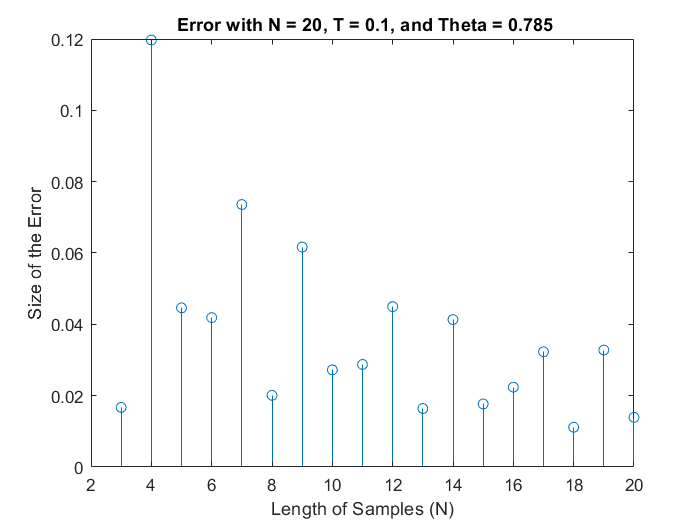

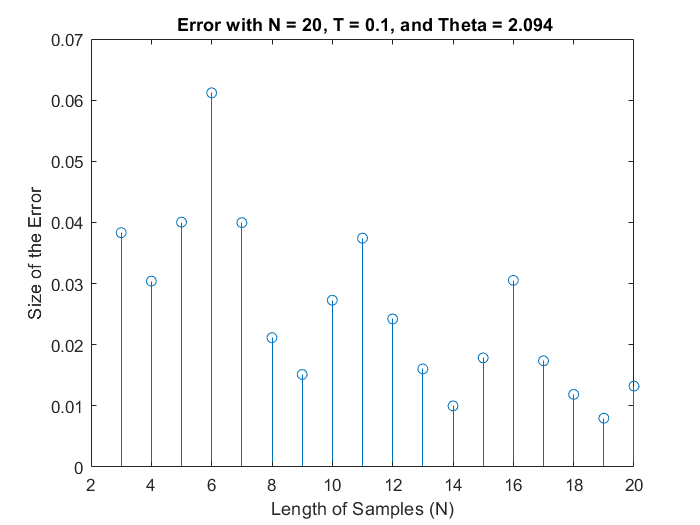

e_max = zeros(1,18);
for Theta = [pi/4 2*pi/3]
    for N = 3:20
        n = 0:N;
        x = cos(2*pi*F*T*n + Theta);
        [xhat,t] = PROJECT1(x,N,T);
        xa = cos(2*pi*F*t + Theta);
        e = xa - xhat;
        e_max(N-2) = max(abs(e(round(1/3*length(xa)):round(2/3*length(xa)))));
    end
    figure
    stem(3:length(e_max)+2,e_max)
    xlabel('Length of Samples (N)');
    ylabel('Size of the Error');
    title(sprintf(' Error with N = %d, T = 0.1, and Theta = %1.3f',N,Theta))
end

## *Section 2: Sunspots*

## Part A

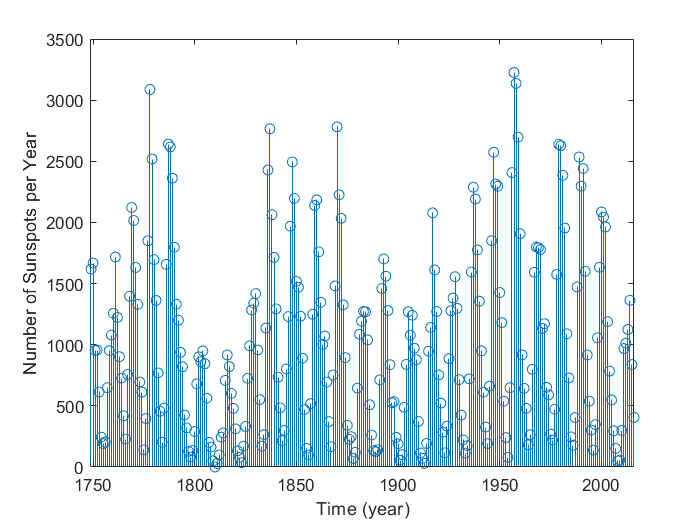

clear
fileID = fopen('SN_m_tot_V2.0.txt','r');
formatSpec = '%d %d %f %f %f %d';
sizeA = [6 Inf];
A = fscanf(fileID,formatSpec,sizeA);

num_ss_month = A(4,:);
year = linspace(1749,2016,268);

num_ss_year = zeros(1,268);
for i = 1:12:3204
    num_ss_year(A(1,i)-1748) = sum(A(4,i:i+11));
end
num_ss_year(A(1,3205)-1748) = sum(A(4,3205:3213));

stem(year,num_ss_year)
xlabel('Time (year)')
ylabel('Number of Sunspots per Year')
xlim([1749,2016])

## Part B

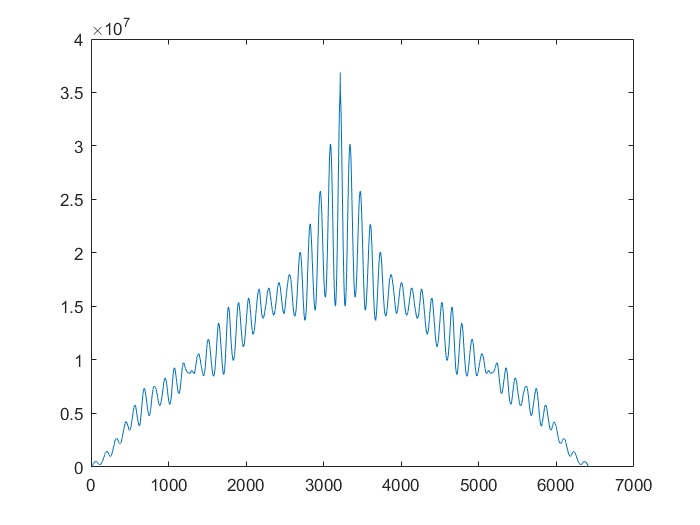

Rnn = xcorr(num_ss_month);
figure
plot(Rnn)

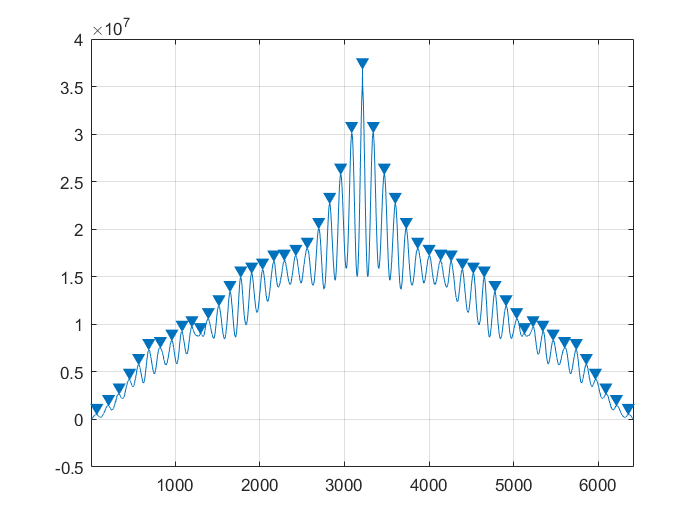

findpeaks(Rnn,'MinPeakDistance',72)

[~,locsn]=findpeaks(Rnn,'MinPeakDistance',72); 
Tn=mean(diff(locsn)); % Tn = 125.76 months

## Part C

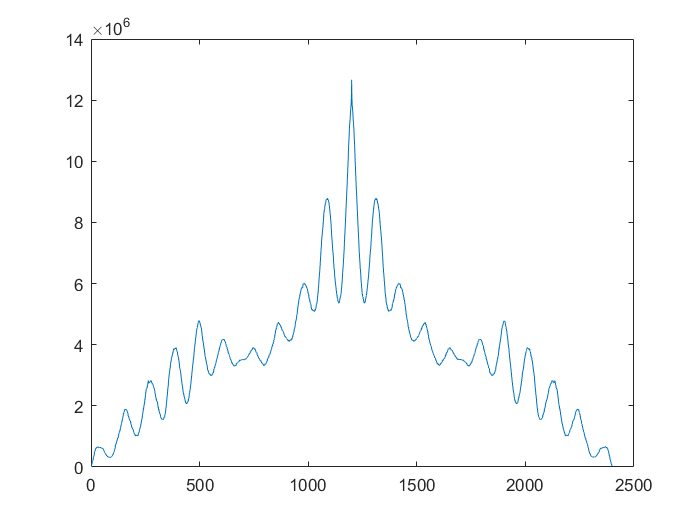

% 1749-1848
Rnn1749_1848 = xcorr(num_ss_month(1:1200));
figure
plot(Rnn1749_1848)

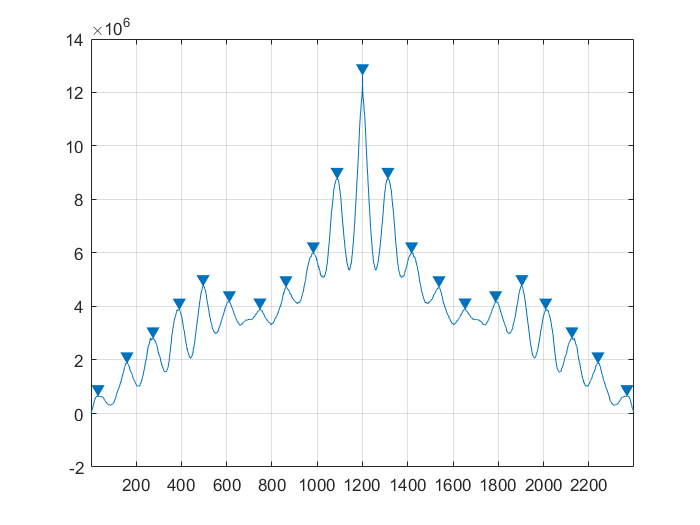

findpeaks(Rnn1749_1848,'MinPeakDistance',72)

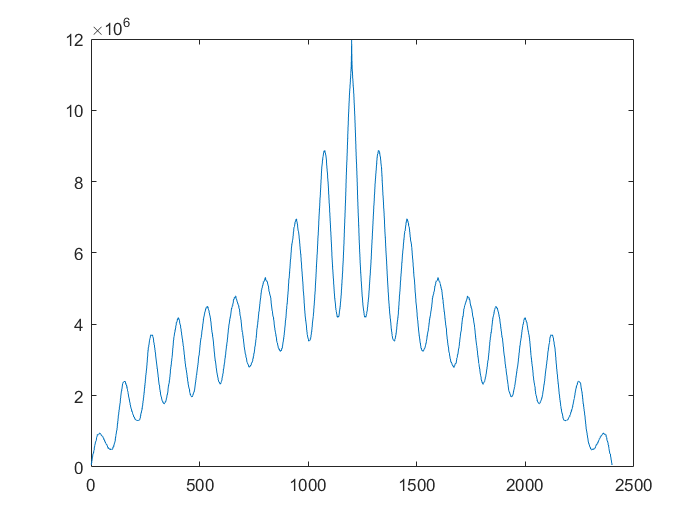

[~,locsn]=findpeaks(Rnn1749_1848,'MinPeakDistance',72); 
Tn1749_1848=mean(diff(locsn)); % Tn = 116.80 months
% 1849-1948
Rnn1849_1948 = xcorr(num_ss_month(1201:2400));
figure
plot(Rnn1849_1948)

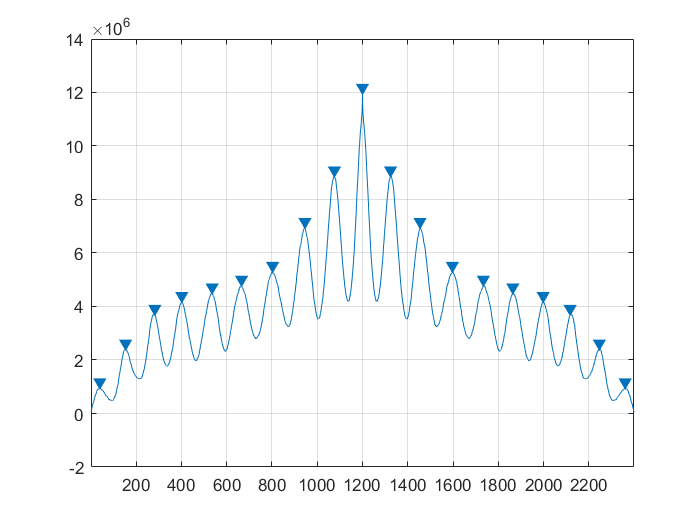

findpeaks(Rnn1849_1948,'MinPeakDistance',72)

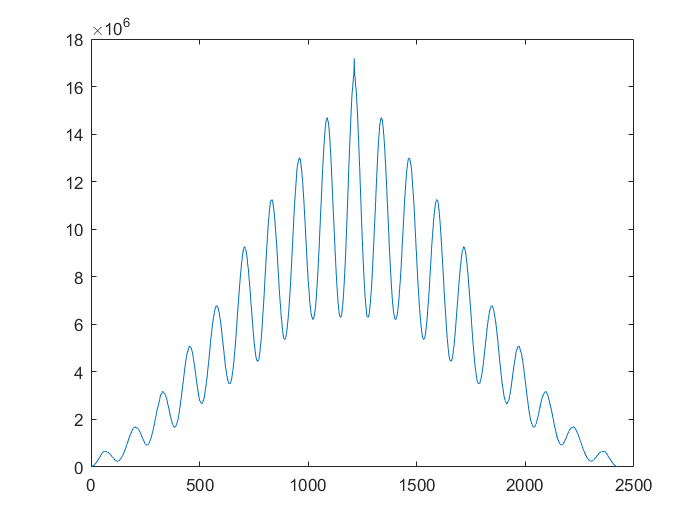

[~,locsn]=findpeaks(Rnn1849_1948,'MinPeakDistance',72); 
Tn1849_1948=mean(diff(locsn)); % Tn = 128.89 months
% 1915-2015
Rnn1915_2015 = xcorr(num_ss_month(1993:3204));
figure
plot(Rnn1915_2015)

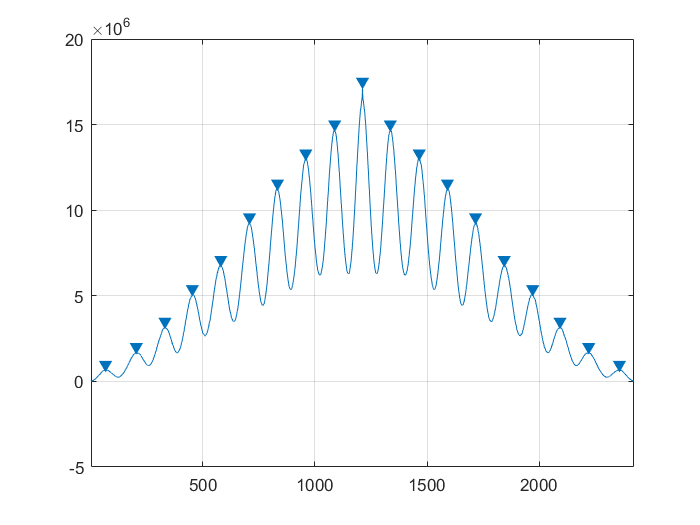

findpeaks(Rnn1915_2015,'MinPeakDistance',72)

[~,locsn]=findpeaks(Rnn1915_2015,'MinPeakDistance',72); 
Tn1915_2015=mean(diff(locsn)); % Tn = 127.33 months

## Part D

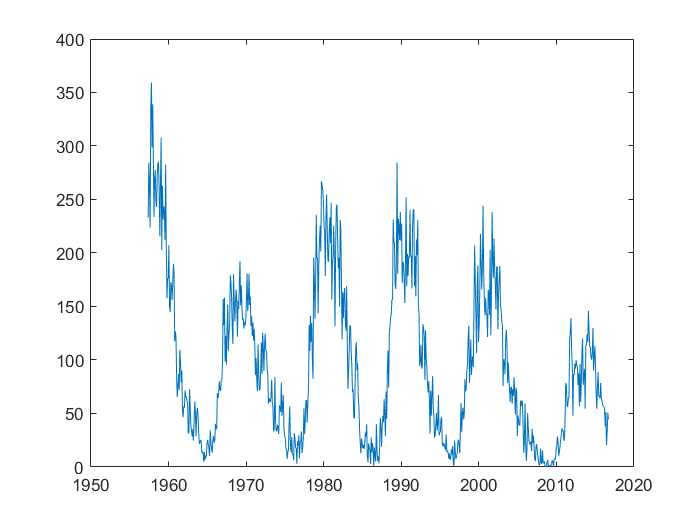

plot(A(3,2501:3213),num_ss_month(2501:3213))

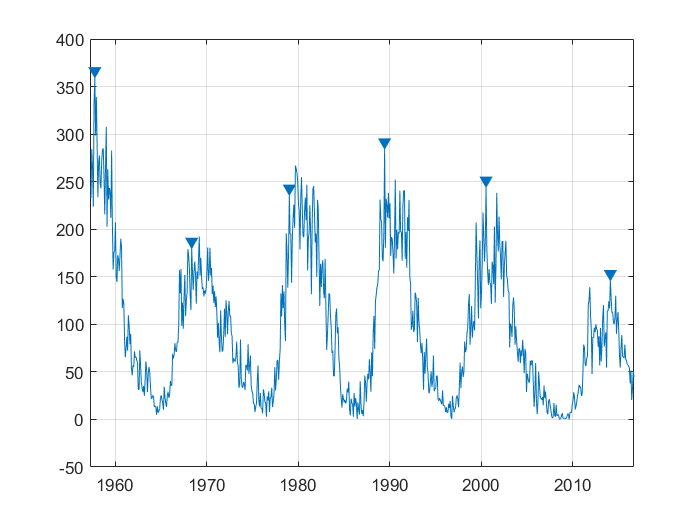

findpeaks(num_ss_month(2501:3213),A(3,2501:3213),'MinPeakDistance',10)